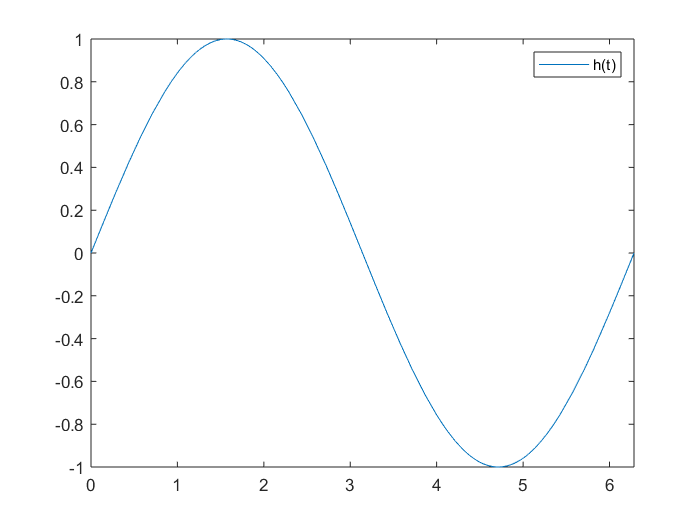

syms h(t)

% where Vref = 1V
h(t) = sin(t);

% plot the sine function
fplot(h(t), [0, 2*pi])
legend({'h(t)'},'Location','northeast')
hold off

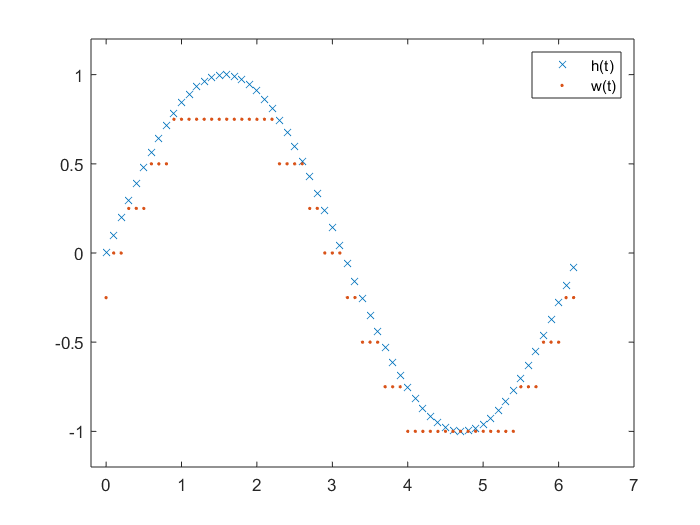


% find the w(t) function and the quant noise
t = [0:.1:2*pi]; % Times at which to sample the sine function
sig = sin(t); % Original signal, a sine wave
partition = [-1:.25:1]; % Length 11, to represent 12 intervals
codebook = [-1.25:.25:1]; % Length 12, one entry for each interval
[index,quants] = quantiz(sig,partition,codebook); % Quantize.
plot(t,sig,'x',t,quants,'.')
legend('h(t)','w(t)');
axis([-.2 7 -1.2 1.2])
hold off;

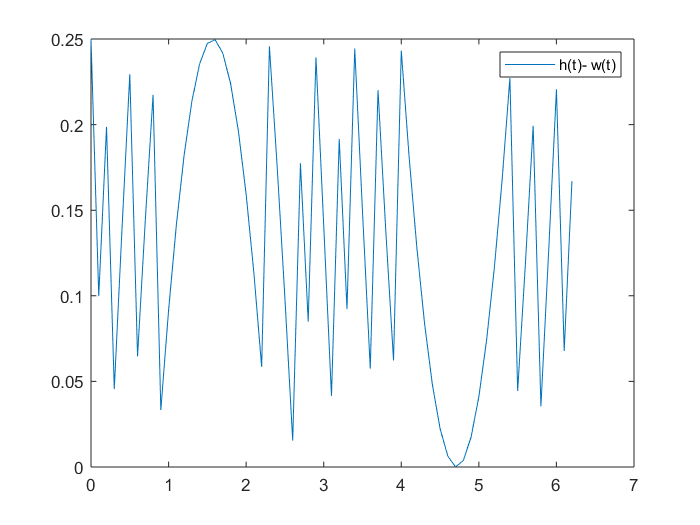

qnoise = sig - quants;
t = [0:0.1:2*pi];
plot(t, qnoise)
legend({'h(t)- w(t)'},'Location','northeast')